# Exercise: Neural Network Verification

This exercise should give you a high-level understanding of neural network verification.

## Neural Networks

Neural network [1] are usually defined layer-wise:


$$h_k =L_k (h_{k-1} )\;\textrm{=}\;\left\lbrace \begin{array}{ll}
{\textrm{W}}_k \;{\textrm{h}}_{k-1} \;\textrm{+}\;{\textrm{b}}_k  & \textrm{linear}\\
\sigma_{k\left(h_{k-1} \right)}  & \textrm{nonlinear}
\end{array}\right.\textrm{
}$$


where $h_{k-1}$ is the input of layer $k$, $W_k \;$and $b_k$ the weight and bias of the linear layer, and $\sigma_k$ the activation function.

Finally, with input $x$ and output $y$ and $K$ layers, a neural network is defined as follows:


$$\begin{array}{l}
h_0 \;\textrm{=}\;\textrm{x}\;\\
\;{\textrm{h}}_k \;\textrm{=}\;{\textrm{L}}_k {\textrm{(h}}_{k-1} \textrm{),}~\textrm{k=1}\ldots\textrm{K}\;\\
\textrm{
}\;\textrm{y}\;\textrm{=}\;{\textrm{h}}_K 
\end{array}$$
 

The behavior of neural networks is still a blackbox, where the output can lead to surprising results [2].

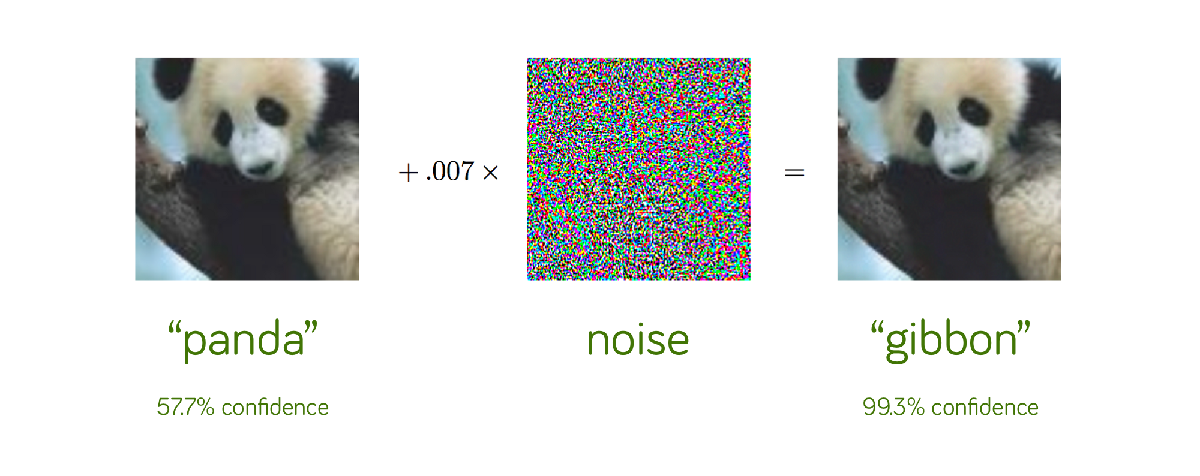

Due to these *adversarial examples*, the applicability of neural networks in safety-critical environments is limited (see car example in last tutorial).

Thus, the verification of neural networks became more important in the recent years.

## Introduction: Neural Network Verification

### Neural Networks

Before we start to initialize our network, let's set a seed for reproducability.

seed = randi(1000);
seed = 608; % comment this line out to get a new random NN every time.
rng(seed)
fprintf("Seed: %d\n", seed);

Seed: 608


We will create a 3-layer neural network with randomly initialized weights. Of course, in practice we would read the real weights from our trained network instead.

We use 2 input neurons and 2 output neurons for easy visualizations.

% neurons per layer
neurons = [2, 5, 5, 2];

W = cell(length(neurons)-1, 1);
b = cell(length(neurons)-1, 1);

for i = 1:length(neurons) - 1
    W{i} = rand(neurons(i+1), neurons(i)) * 2 - 1;
    b{i} = rand(neurons(i+1), 1) * 2 - 1;
end

Now we can create our network: (see `./cora/global/classes/nn` for more)

layers = cell(length(W)*2, 1);
for i = 1:length(W)
    layers{2*i-1} = nnLinearLayer(W{i}, b{i});
    layers{2*i} = nnTanhLayer();
end
nn_cora = neuralNetwork(layers);
display(nn_cora);

nn_cora =

Neural network: 'neuralNetwork'
Nr. of input neurons: 2
Nr. of output neurons: 2

layers: (6 layers)
 (1)	 nnLinearLayer                  nnLinearLayer_1                       2x1 -> 5x1       
 (2)	 nnTanhLayer                    nnTanhLayer_2                         5x1 -> 5x1       
 (3)	 nnLinearLayer                  nnLinearLayer_3                       5x1 -> 5x1       
 (4)	 nnTanhLayer                    nnTanhLayer_4                         5x1 -> 5x1       
 (5)	 nnLinearLayer                  nnLinearLayer_5                       5x1 -> 2x1       
 (6)	 nnTanhLayer                    nnTanhLayer_6                         2x1 -> 2x1       



Note there is also a `generateRandom `function to generate a random neural network (Such a function also exists for all set representations).

nn_cora2 = neuralNetwork.generateRandom("NrInputs", 2, "NrOutputs", 2, "ActivationFun", "tanh")

nn_cora2 =

Neural network: 'neuralNetwork'
Nr. of input neurons: 2
Nr. of output neurons: 2

layers: (4 layers)
 (1)	 nnLinearLayer                  nnLinearLayer_7                       2x1 -> 5x1       
 (2)	 nnTanhLayer                    nnTanhLayer_8                         5x1 -> 5x1       
 (3)	 nnLinearLayer                  nnLinearLayer_9                       5x1 -> 2x1       
 (4)	 nnTanhLayer                    nnTanhLayer_10                        2x1 -> 2x1       



### Set Propagation

Now we can define the input set we want to verify. We will use polynomial zonotopes [3] here. Additionally, we can randomly draw some samples from this input set and plot them as well.

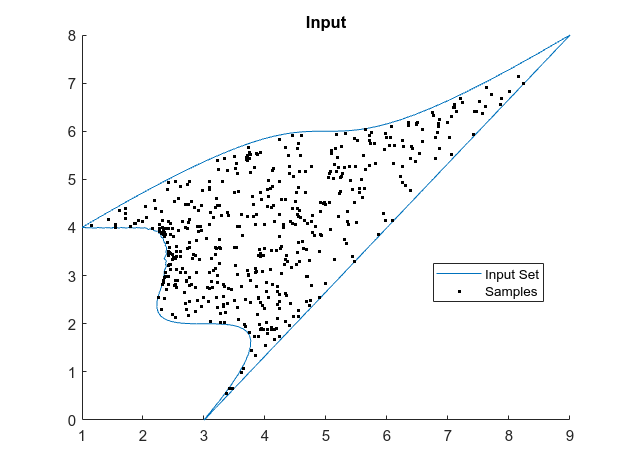

c = [4; 4];
G = [2, 1, 2; 0, 2, 2];
expMat = [1, 0, 3; 0, 1, 1];
Grest = [];
X = polyZonotope(c, G, Grest, expMat);
xs = X.randPoint(500);

figure;
hold on;
plot(X, [1, 2], "DisplayName", "Input Set");
scatter(xs(1, 1:end), xs(2, 1:end), 'k', 'Marker', '.', "DisplayName", "Samples");
legend('Location', 'best')
title("Input")

With traditional neural network inference, we would propagate these samples through the network and obtain the results for these dots:

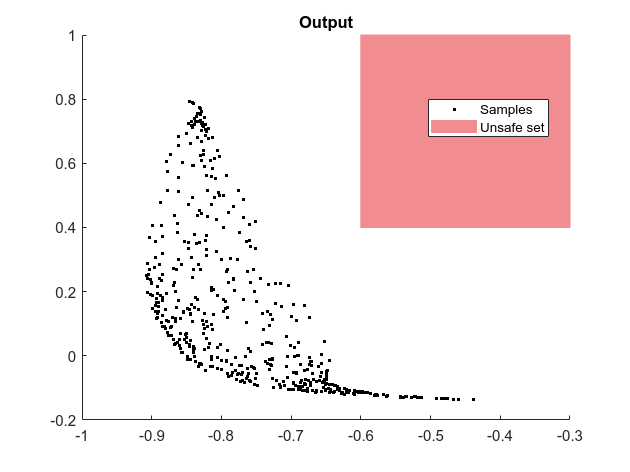

ys = nn_cora.evaluate(xs);

unsafeSet = specification(interval([-0.6;0.4], [-0.3; 1]), 'unsafeSet');

figure; hold on;
scatter(ys(1, 1:end), ys(2, 1:end), 'k', "Marker", '.', "DisplayName", "Samples")
plot(unsafeSet, [1 2], "DisplayName", "Unsafe set")
legend('Location', "best")
title("Output")

The red area defines an unsafe region. Our goal is to verify that the network does not output anything within this area. Just looking at the samples is not enough because there might be outliers we have missed. On the other hand, if some samples land in the unsafe region, we can confirm unsafety.

check(unsafeSet, ys)

ans = logical
   1


For Neural Network Verification, we want to propagate the whole set through the network. This allows us to make statements over the whole input set rather than individual samples. Especially, think about outliers: We might miss them if we just propagate individual samples through the network, whereas we would have them included if we propagate the whole input set.

### Layer Propagation

The set propagation works layer-by-layer. We need to define an image enclosure for each layer, allowing us to propagate the set itself through the current layer for each set representation. The result of the current layer is then passed into the next layer.

#### Linear Layer

Linear layers are rather easy as they make use of a matrix multiplication and all set representations have a linear map operation already implemented. Adding the bias just moves the center of the set representation.

Note that convolutional layers are also just linear layers, thus we can transform the set through these layers similarly [4].

#### Non-Linear Layer

Unfortunately, non-linear layers are not as easy as we can not just evaluate the set representation on an arbitrary function. Let's consider the `tanh(x)` function as a running example.

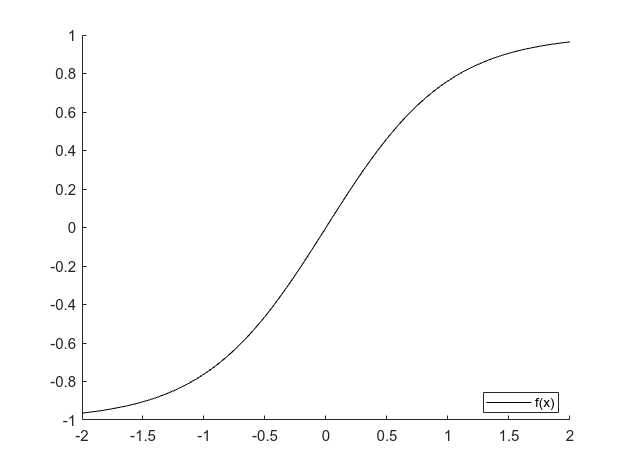

layer = nnTanhLayer();

x_max = linspace(-2, 2, 1000);
y_max = layer.evaluate(x_max);
figure; hold on; 
legend('Location', 'best');
plot(x_max, y_max, 'k', "DisplayName", "f(x)")

#### Polynomial Approximation

We use polynomials to approximate the nonlinaer function as polynomial zonotopes are closed under polynomials, i.e. the result is again a polynomial zonotope. 

Usually, we are only interested in approximating the function within some bounds `[l, u];`

l = -1.7;
u = 1.5;
x = linspace(l, u, 1000);
y = layer.evaluate(x);

A simple and effective way to approximate the function is regression. Here we want to minimize the squared difference between the true function value$y=f\left(x\right)$ and the approximated function value $\hat{y} =p\left(x\right)$: $\min \;{\left(y-\hat{y} \right)}^2$.

For this problem, a closed form solution for the coefficients of the approximation polynomial $p\left(x\right)$ exists and is given by: $\textrm{coeffs}={\left(X^T X\right)}^{-1} X^T y$ with $X\left(i,:\right)=\left\lbrack 1,x_i ,x_i^2 ,\ldotp \ldotp \ldotp ,x_i^n \right\rbrack$.

Thus, we can plot some example polynomials with different orders using regressions:

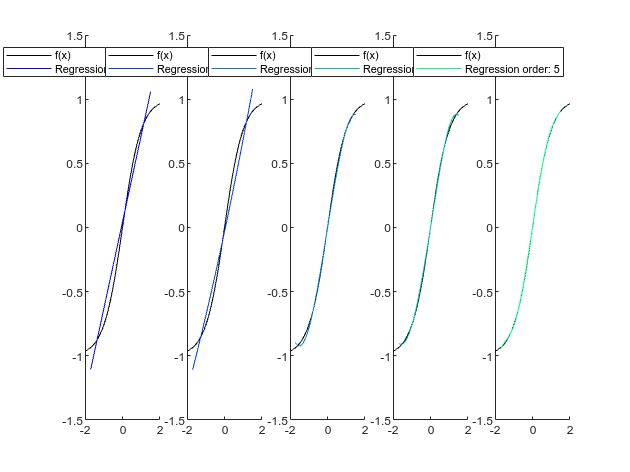

max_order = 5;
cmap = winter(max_order);
figure;
for order = 1:max_order
    subplot(1, max_order, order);
    hold on;
    legend("Location", "north")
    ylim([-1.5,1.5])

    coeffs = layer.computeApproxPoly(l,u,order,'regression');
    y_poly = polyval(coeffs, x);

    plot(x_max, y_max, 'k', "DisplayName", "f(x)");

    plot(x, y_poly, "-", "Color", cmap(order, :), "DisplayName", sprintf("Regression order: %d", order));
end

**! ***Note: If the plot is too tiny, hover over the plot and click on the arrow on the top right. This should open the plot in a new window which you can resize to your needs. The code needs to be executed before.*

Pretty good approximations, right? BUT as we want to verify our networks and not just approximate them, we need to include an error term `d` into our image enclosure. This is given by the maximum difference between the approximation and the true value. Adding this error term leads to an **over-approximation **of the output set.

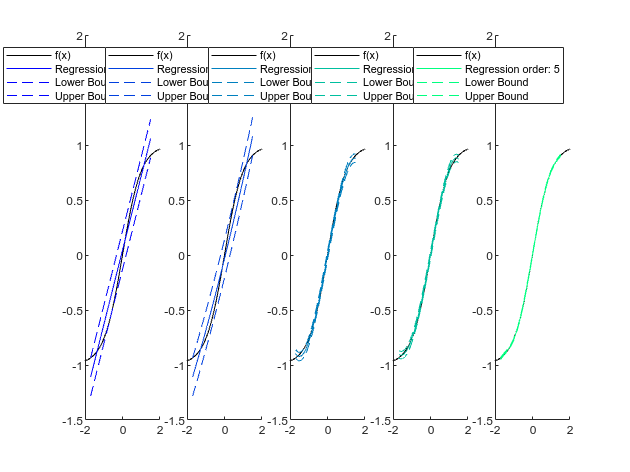

max_order = 5;
cmap = winter(max_order); % color

figure;
for order = 1:max_order
    subplot(1, max_order, order);
    hold on;
    legend("Location", "north")
    ylim([-1.5,2])

    coeffs = layer.computeApproxPoly(l,u,order,'regression');
    y_poly = polyval(coeffs, x);
    [coeffs, d] = layer.computeApproxError(l,u,coeffs);

    % compute the difference between activation function and regression fit
    y_poly = polyval(coeffs, x);

    plot(x_max, y_max, 'k', "DisplayName", "f(x)")
    plot(x, y_poly, "-", "Color", cmap(order, :), "DisplayName", sprintf("Regression order: %d", order));
    plot(x, y_poly-d, "--", "Color", cmap(order, :), "DisplayName", "Lower Bound");
    plot(x, y_poly+d, "--", "Color", cmap(order, :), "DisplayName", "Upper Bound");
end

**! ***Note: If the plot is too tiny, hover over the plot and click on the arrow on the top right. This should open the plot in a new window which you can resize to your needs. The code needs to be executed before.*

Now we have successfully defined the image enclosure of non-linear functions using regression.

#### Hand-Crafted Approximation

Regression is not the only way to approximate non-linear functions. Sometimes, it can be usefull to use hand-crafted approximations by exploiting certain features of the function, e.g. that `tanh(x)` has an S-Shape or ReLU activations are piece-wise linear [5].

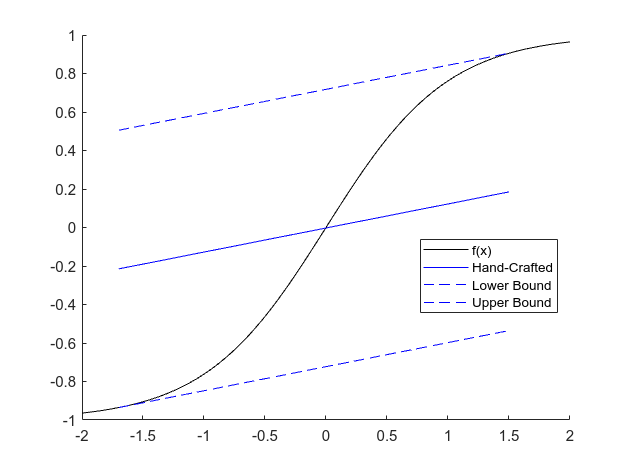

max_order = 1;
figure;
for order = 1:max_order
    subplot(1, max_order, order);
    hold on;
    legend("Location", "best")

    coeffs = layer.computeApproxPoly(l,u,order,'singh');
    y_poly = polyval(coeffs, x);
    [coeffs, d] = layer.computeApproxError(l,u,coeffs);

    y_poly = polyval(coeffs, x);

    plot(x_max, y_max, 'k', "DisplayName", "f(x)")
    plot(x, y_poly, "-", "Color", cmap(order, :), "DisplayName", sprintf("Hand-Crafted", order));
    plot(x, y_poly-d, "--", "Color", cmap(order, :), "DisplayName", "Lower Bound");
    plot(x, y_poly+d, "--", "Color", cmap(order, :), "DisplayName", "Upper Bound");
end;

Although the approximation might not look as good, it has a usefull property: The output domain of our approximation matches the output domain of the true function, which is not the case for regression. This can help to get tighter bounds.

### Neural Network Verification Example

Now that we have a high-level understanding of how the propagation works, let's try to verify the network defined at the beginning of this tutorial.

#### Regression Example

Let's start off with the regression approximation. To see the difference between the different orders of approximation we start with a linear polynomial approximation on all layers and then adaptively refine the network where we expect the most benefit, i.e. at the layer where the error bound is the largest. 

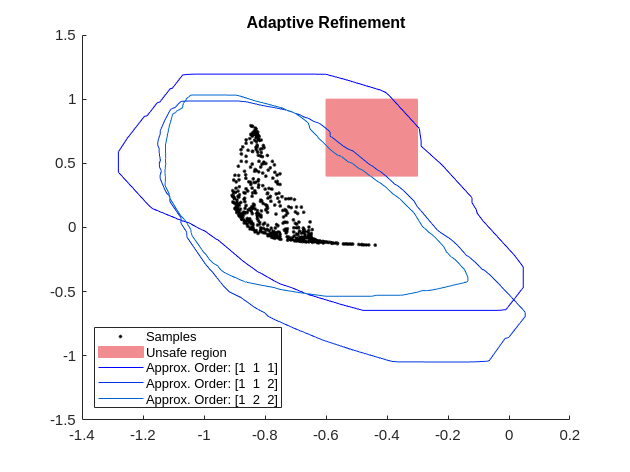

---


Step 1:


- 0.093071 seconds.


Refined layer 3 from order 1 to 2!


---


Step 2:


- 0.006955 seconds.


Refined layer 2 from order 1 to 2!


---


Step 3:


- 0.008576 seconds.


Refined layer 1 from order 1 to 2!


---


Step 4:


- 0.010231 seconds.


warning off;
num_refinements = 6;
max_order = 5;

cmap = winter(num_refinements);
nn_cora.reset();

% init plot
figure;
hold on;
legend('Location', 'southwest')
title("Adaptive Refinement")
scatter(ys(1, 1:end), ys(2, 1:end), 'k', "Marker", '.', "DisplayName", "Samples")
plot(unsafeSet, [1 2], "DisplayName", "Unsafe region")

% nn evaluation settings (more about them next week)
evParams = struct;
evParams.poly_method = 'regression';
evParams.bound_approx = false;
evParams.reuse_bounds = true;
evParams.num_generators = 100000;

% run 
for i = 1:num_refinements
    disp("---")
    disp(sprintf("Step %d:", i));
    tic
    % propagate through the network
    Y = nn_cora.evaluate(X, evParams);
    t = toc;
    disp(sprintf("- %f seconds.", t));

    % reduce for plotting
    Y = reduce(Y, 'girard', 1000);

    refs = [];
    refinable_layers = nn_cora.getRefinableLayers();
    for j=1:length(refinable_layers)
        refs = [refs, max(refinable_layers{j}.order)];
    end
    
    % plotting can be quite slow
    plot(Y, [1, 2], '-', "DisplayName", sprintf(['Approx. Order: [', num2str(refs), ']']), "Color", cmap(i, :))
    drawnow

    nn_cora.refine(5, "layer","both",X.c,true)
end

The red area defines an unsafe region and our goal is to verify that the network does not output anything within this area. Again, just looking at the samples is not enough because there might be outliers we have missed.

With our set propagation, we cannot confirm safety in the first couple of steps as our over-approximation intersects with the unsafe region. We can also not confirm unsafety as we calculated an over-approximation. 

Refining the over-approximation further yields us with safety confirmation. Congratulations, you have just verified your first neural network!

Unfortunately, higher order approximation leads to an explosion in the size of the set representation - especially if done sequentially in each layer - thus, here is still some work to do to make it scalable.

#### Hand-Crafted Example

Lastly, the following will calculate an over-approximation using the hand-crafted approximation technique.

nn_cora.reset();
evParams.poly_method = 'singh';
Y_hand = nn_cora.evaluate(X, evParams);

figure; hold on;
legend('Location', 'best')
title("Hand-Crafted Example")
plot(unsafeSet, [1 2], "DisplayName", "Unsafe region")
scatter(ys(1, :), ys(2, :), 'k', "Marker", '.', "DisplayName", "Samples")
plot(Y_hand, [1, 2], 'c', "DisplayName", "Hand-crafted Approach")

This approximation approach can lead to very tight bound estimations (see y-axis), although that is not guaranteed (see x-axis).

Note that we can also combine both approaches, that is calculate the output sets using both approximations and use the intersection of both as an even tighter over-approximation.

figure; hold on;
legend('Location', 'best')
title("Intersection")
plot(unsafeSet, [1 2], "DisplayName", "Unsafe region U_1")
plot(specification(interval([-1;-0.4],[0;-0.2]),'unsafeSet'), [1 2], "DisplayName", "Unsafe region U_2")
scatter(ys(1, 1:end), ys(2, 1:end), 'k', "Marker", '.', "DisplayName", "Samples")
plot(Y_hand, [1, 2], 'c', "DisplayName", "Hand-crafted Approach")
plot(Y, [1, 2], '-', "DisplayName", sprintf(['Regression Order: [', num2str(refs), ']']), "Color", cmap(end, :))

## Outlook: Neural-Network-Controlled Systems

As an outlook, we could also embed a neural network in a dynamic system we have seen in `02_exercise_cora.`

In this example, a NN-controlled car is following a leading car. The goal of the NN-car is to keep a safe distance to the leading car. We want to verify this goal.

The neural network is evaluated every $\Delta \;t=0\ldotp 1$ and its output is used as constant input to the dynamic system for the next time interval $\left\lbrack \;t;\;t+\Delta \;t\right\rbrack$.

In the plot below, we can see that the NN-car is 80-100m behind the leading car at time 0 and is able to keep the safe distance to the leading car within the next 5 seconds.

example_neuralNet_reach_02_ACC();

Or another model of a simplified car model: Here, the car tries to reach a goal set within 5 seconds.

example_neuralNet_reach_01_unicycle();

## Tasks

- Run the code.

- Interpret the results.

- Play around with different values (neural networks, other sets, ...).

- Get a intuition for neural network verification.

- Have a look into the references below.

Any question? Just ask!

Next week we will have a deeper look at how the propagation works on polynomial zonotopes. 

### Export to PDF

filePath = matlab.desktop.editor.getActiveFilename;
pdfPath = convertStringsToChars(strrep(filePath, ".mlx", ".pdf"));
matlab.internal.liveeditor.openAndConvert (filePath, pdfPath);

## References

[1] Bishop, C. M., & Nasrabadi, N. M. (2006). *Pattern recognition and machine learning* (Vol. 4, No. 4, p. 738). New York: springer. [https://www.cs.uoi.gr/~arly/courses/ml/tmp/Bishop_book.pdf](https://www.cs.uoi.gr/~arly/courses/ml/tmp/Bishop_book.pdf)

[2] Goodfellow, I. J., Shlens, J., & Szegedy, C. (2014). Explaining and harnessing adversarial examples. *arXiv preprint arXiv:1412.6572*.

[3] Kochdumper, N., & Althoff, M. (2020). Sparse polynomial zonotopes: A novel set representation for reachability analysis. *IEEE Transactions on Automatic Control*, *66*(9), 4043-4058.

[4] Gehr, T., Mirman, M., Drachsler-Cohen, D., Tsankov, P., Chaudhuri, S., & Vechev, M. (2018, May). Ai2: Safety and robustness certification of neural networks with abstract interpretation. In *2018 IEEE Symposium on Security and Privacy (SP)* (pp. 3-18). IEEE.

[5] Singh, G., Gehr, T., Mirman, M., Püschel, M., & Vechev, M. (2018). Fast and effective robustness certification. *Advances in neural information processing systems*, *31*.